# Questão 4

Considerar as seguintes modulações:

- BPSK

- QPSK

- 8-PSK

- 16-QAM

- 64-QAM

**Critério de seleção**: maximização da eficiência espectral para um desempenho de probabilidade de erro de bit limitante $P_b$.

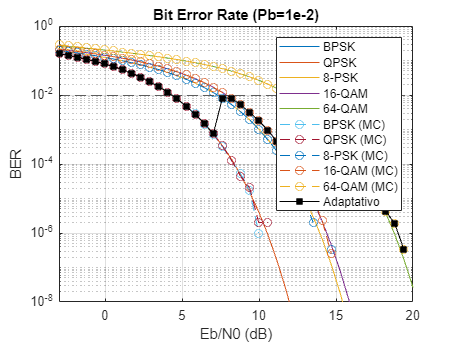

rng('default')


eb_n0_dB = linspace(-3,20,40);
eb_n0 = 10.^(eb_n0_dB./10);

% Valores teóricos
bpsk_teorica = berawgn(eb_n0_dB, 'psk', 2, 'nondiff');
qpsk_teorica = berawgn(eb_n0_dB, 'psk', 4, 'nondiff');
psk8_teorica = berawgn(eb_n0_dB, 'psk', 8, 'nondiff');
qam16_teorica = berawgn(eb_n0_dB, 'qam', 16);
qam64_teorica = berawgn(eb_n0_dB, 'qam', 64);

% Valores simulados por Monte Carlo
bpsk_mc = m_psk(eb_n0, 2);
qpsk_mc = m_psk(eb_n0, 4);
psk8_mc = m_psk(eb_n0, 8);
qam16_mc = m_qam(eb_n0, 16);
qam64_mc = m_qam(eb_n0, 64);

% Valor do adaptativo usando cache pré-computado (opcional, apenas para melhor desempenho)
mcache(1,:) = qam64_mc;
mcache(2,:) = qam16_mc;
mcache(3,:) = psk8_mc;
mcache(4,:) = qpsk_mc;
mcache(5,:) = bpsk_mc;
pb_max = 1e-2;
adp = adaptativo(pb_max, eb_n0, mcache);


figure();
semilogy(eb_n0_dB, bpsk_teorica); hold on;
semilogy(eb_n0_dB, qpsk_teorica);
semilogy(eb_n0_dB, psk8_teorica);
semilogy(eb_n0_dB, qam16_teorica);
semilogy(eb_n0_dB, qam64_teorica);
semilogy(eb_n0_dB, bpsk_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qpsk_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, psk8_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qam16_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qam64_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, adp, 'k', 'LineStyle', '-', 'Marker', 'square', 'MarkerFaceColor', 'k');
yline(pb_max, 'LineStyle', '--');
hold off;
grid on;

title('Bit Error Rate (Pb=1e-2)');
xlabel('Eb/N0 (dB)');
ylabel('BER');
xlim([eb_n0_dB(1) eb_n0_dB(length(eb_n0_dB))]);
ylim([1e-8 1]);
legend('BPSK', 'QPSK', '8-PSK', '16-QAM', '64-QAM', ...
    'BPSK (MC)', 'QPSK (MC)', '8-PSK (MC)', '16-QAM (MC)', '64-QAM (MC)', 'Adaptativo');

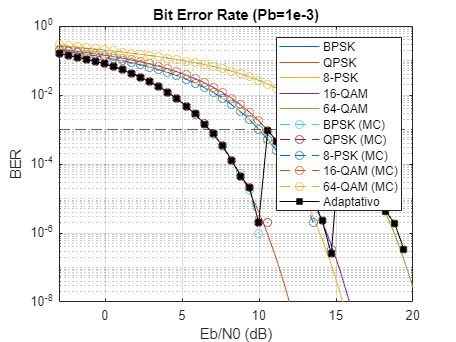

pb_max = 1e-3;
adp = adaptativo(pb_max, eb_n0, mcache);
figure();
semilogy(eb_n0_dB, bpsk_teorica); hold on;
semilogy(eb_n0_dB, qpsk_teorica);
semilogy(eb_n0_dB, psk8_teorica);
semilogy(eb_n0_dB, qam16_teorica);
semilogy(eb_n0_dB, qam64_teorica);
semilogy(eb_n0_dB, bpsk_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qpsk_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, psk8_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qam16_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, qam64_mc, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, adp, 'k', 'LineStyle', '-', 'Marker', 'square', 'MarkerFaceColor', 'k');
yline(pb_max, 'LineStyle', '--');
hold off;
grid on;

title('Bit Error Rate (Pb=1e-3)');
xlabel('Eb/N0 (dB)');
ylabel('BER');
xlim([eb_n0_dB(1) eb_n0_dB(length(eb_n0_dB))]);
ylim([1e-8 1]);
legend('BPSK', 'QPSK', '8-PSK', '16-QAM', '64-QAM', ...
    'BPSK (MC)', 'QPSK (MC)', '8-PSK (MC)', '16-QAM (MC)', '64-QAM (MC)', 'Adaptativo');